# `verification_matderiv.mlx`

Example verifying the analytical expression for the time derivative of a rotation matrix in terms of the angular velocity.

% clears Workspace and Command Window, closes all figures
clear; clc; close all;

## Initial conditions.

Angular velocity of frame B with respect to frame A, expressed in frame B.

w_A2B_B = [1;2;3];

Initial attitude of frame B with respect to frame A, represented as a quaternion.

q_A2B_0 = [1;2;3;4]/norm([1;2;3;4]);

## Solving for the quaternion and rotation matrix as a function of time.

Ordinary differential equation defining the quaternion kinematics.

dqdt = @(t,q_A2B) quateqn(q_A2B,w_A2B_B);

Solves the ODE from time $t=0$ to time $t=10\;\mathrm{s}$.

[t,q_A2B] = ode45(dqdt,0:0.01:10,q_A2B_0);
q_A2B = q_A2B';

Gets the rotation matrices at each solution time from the quaternions.

R_A2B = zeros(3,3,length(t));
for i = 1:length(t)
    R_A2B(:,:,i) = quat2mat(q_A2B(:,i));
end

## Derivative of the rotation matrix (numerical).

Extracting the (1,2) element,

R11 = R_A2B(1,2,:);
R11 = R11(:);

Evaluating the derivative numerically,

dR11dt_numerical = diff(R11)./diff(t);

## Derivative of the rotation matrix (analytical).

Skew-symmetric form of the angular velocity.

W = vec2skew(w_A2B_B);

Time derivative of the rotation matrix at each solution time.

dRdt = zeros(size(R_A2B));
for i = 1:length(t)
    dRdt(:,:,i) = -W*R_A2B(:,:,i);
end

Time derivative of the (1,2) element of the rotation matrix.

dR11dt_analytical = dRdt(1,2,:);
dR11dt_analytical = dR11dt_analytical(:);

## Comparison plot.

Plotting both the numerical and analytical results,

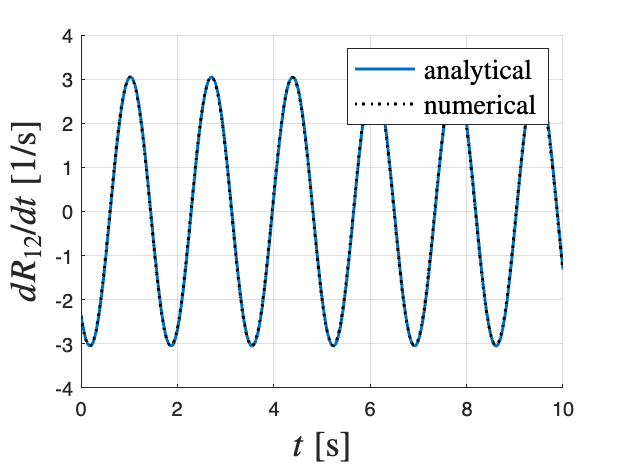

figure;
hold on;
plot(t,dR11dt_analytical,'LineWidth',1.5);
plot(t(1:end-1),dR11dt_numerical,'k:','LineWidth',1.5);
hold off;
grid on;
xlabel('$t\;[\mathrm{s}]$','Interpreter','latex','FontSize',18);
ylabel('$dR_{12}/dt\;[\mathrm{1/s}]$','Interpreter','latex','FontSize',18);
legend('analytical','numerical','Interpreter','latex','FontSize',14);